clear;
clc;

% Y down is progression of turbine stages
% Turbines rotate X ->

% Input parameters
mass_flow_rate = 0.34; % kg/s
temperature = 1200; % F
radius = 0.04; % meters
rpm = 80000; % revolutions per minute
horse_power = 200; % HP
torque = horse_power/(rpm/5252); % N*m
% fluid_velocity = 100;  % m/s
degree_of_reaction = 0;
num_blades = 10;
beta1 = deg2rad(35); % rotor blade angle
beta2 = deg2rad(-35); % impulse turbine rotor so angle is just negative
alpha1 = deg2rad(60); % fluid velocity from stator
chord = 0.04; % m
stagger_angle = (beta1 + beta2) / 2;

[v1, v2, w1, w2, a1, a2, u] = rotorBackCalculate2(rpm, torque / num_blades, mass_flow_rate, beta1, beta2, alpha1, radius);

C param: 96.544
Betas: 0.611, -0.611
Inlet Absolute Velocity (V_in): 649.52 m/s
Outlet Absolute Velocity (V_out): 462.78 m/s
Inlet Relative Velocity (W_in): 396.46 m/s
Outlet Relative Velocity (W_out): 564.78 m/s
Inlet Relative Angle (a_in): 60.00 deg
Outlet Relative Angle (a_out): 1.38 deg
Turbine velocity (u): 335.10 m/s


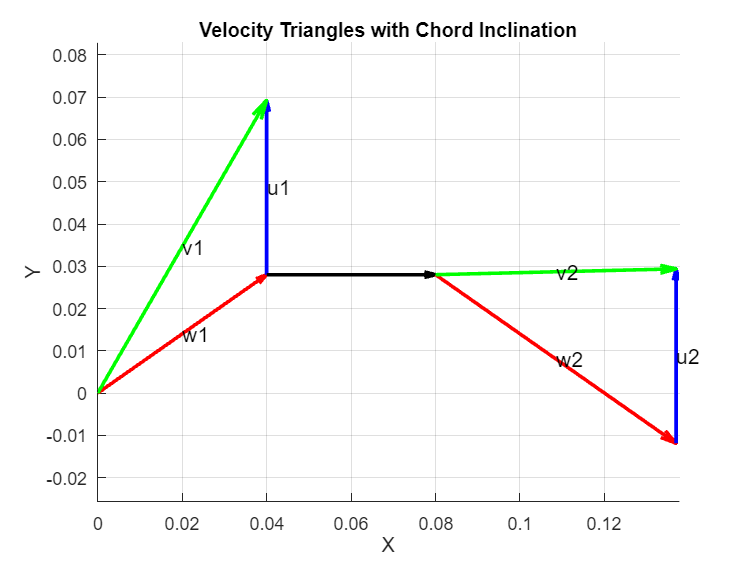

plot_velocity_triangles_angles(v1, v2, u, u, w1, w2, chord, stagger_angle, beta1, beta2, a1, a2);


efficiency = calculate_blade_efficiency(mass_flow_rate, v1, v2, w1, w2, beta1, beta2, a1)    

efficiency = 0.3031

% u1 = [-1, -1];
% u2 = [1, 1];
% w1 = [-1, 1];
% w2 = [-2, -1];
% v1 = u1 + w1;
% v2 = u2 + w2;
% chord_length = 3;
% inclination_angle = deg2rad(30);
% 
% plot_velocity_triangles(v1, v2, u1, u2, w1, w2, chord_length, inclination_angle);


function U = calc_blade_speed(radius, rpm)
    % rpm to angular velocity (rad/s)
    omega = rpm * 2 * pi / 60;

    U = [radius * omega, 0];  % blade speed (m/s)
end

function [v1, v2, w1, w2, a1, a2, U] = rotorBackCalculate(RPM, torque, mass_flow, beta_in, beta_out, radius)
    % Convert RPM to angular velocity (rad/s)
    U = calc_blade_speed(radius, RPM);
    U = U(1);
    
    C = torque / radius / mass_flow;
    % C = 4 * U;
    fprintf("C param: %.3f\n", C);
    fprintf("Betas: %.3f, %.3f\n", beta_in, beta_out);

    % beta_out = -beta_out;

    % w1 = (C) / (sin(beta_in) + tan(beta_out) * cos(beta_in)) + 3 * U;
    w1 = (C) / (tan(beta_out) * cos(beta_in) - sin(beta_in)) + 3 * U;
    a1 = atan2((w1 * sin(beta_in) + U) , (w1 * cos(beta_in)));
    v1 = w1 * cos(beta_in) / cos(a1);

    % w2 = -(v1 * sin(a1) - C + U) / sin(beta_out);
    w2 = w1 * cos(beta_in) / cos(beta_out);
    a2 = atan2((w2 * sin(beta_out) - U) , (w2 * cos(beta_out)));
    v2 = w2 * cos(beta_out) / cos(a2);

    % go back to abs angle measures
    % a2 = -a2;
    % beta_out = -beta_out;
    
    % disp results
    fprintf('Inlet Absolute Velocity (V_in): %.2f m/s\n', v1);
    fprintf('Outlet Absolute Velocity (V_out): %.2f m/s\n', v2);
    fprintf('Inlet Relative Velocity (W_in): %.2f m/s\n', w1);
    fprintf('Outlet Relative Velocity (W_out): %.2f m/s\n', w2);
    fprintf('Inlet Relative Angle (a_in): %.2f deg\n', rad2deg(a1));
    fprintf('Outlet Relative Angle (a_out): %.2f deg\n', rad2deg(a2));
    fprintf('Turbine velocity (u): %.2f m/s\n', U);
end

function [v1, v2, w1, w2, a1, a2, U] = rotorBackCalculate2(RPM, torque, mass_flow, beta_in, beta_out, alpha_in, radius)
    % Convert RPM to angular velocity (rad/s)
    U = calc_blade_speed(radius, RPM);
    U = U(1);
    
    C = torque / radius / mass_flow;
    % C = 4 * U;
    fprintf("C param: %.3f\n", C);
    fprintf("Betas: %.3f, %.3f\n", beta_in, beta_out);

    w1 = U / (cos(beta_in) * tan(alpha_in) - sin(beta_in));
    a1 = alpha_in;
    v1 = w1 * cos(beta_in) / cos(alpha_in);

    w2 = abs((C + v1 * sin(alpha_in) - U) / sin(beta_out));
    a2 = atan2((w2 * sin(beta_out) + U) , (w2 * cos(beta_out)));
    v2 = w2 * cos(beta_out) / cos(a2);
    
    % disp results
    fprintf('Inlet Absolute Velocity (V_in): %.2f m/s\n', v1);
    fprintf('Outlet Absolute Velocity (V_out): %.2f m/s\n', v2);
    fprintf('Inlet Relative Velocity (W_in): %.2f m/s\n', w1);
    fprintf('Outlet Relative Velocity (W_out): %.2f m/s\n', w2);
    fprintf('Inlet Relative Angle (a_in): %.2f deg\n', rad2deg(alpha_in));
    fprintf('Outlet Relative Angle (a_out): %.2f deg\n', rad2deg(a2));
    fprintf('Turbine velocity (u): %.2f m/s\n', U);
end

function plot_velocity_triangles(v1, v2, u1, u2, w1, w2, chord_length, inclination_angle)
    figure;
    hold on;
    axis equal;
    grid on;
    
    % plot w1, u1, and v1
    quiver(0, 0, w1(1), w1(2), 0, 'r', 'LineWidth', 2);
    quiver(w1(1), w1(2), u1(1), u1(2), 0, 'b', 'LineWidth', 2);
    quiver(0, 0, v1(1), v1(2), 0, 'g', 'LineWidth', 2);
    
    % plot the black bar for chord with the inclination angle
    theta = inclination_angle;
    chord_vec = chord_length * [cos(theta), sin(theta)];
    quiver(w1(1), w1(2), chord_vec(1), chord_vec(2), 0, 'k', 'LineWidth', 2);
    
    % get end pt after chord
    chord_end = w1 + chord_vec;
    
    % plot w2, u2, and v2
    quiver(chord_end(1), chord_end(2), w2(1), w2(2), 0, 'r', 'LineWidth', 2);
    quiver(chord_end(1) + w2(1), chord_end(2) + w2(2), u2(1), u2(2), 0, 'b', 'LineWidth', 2);
    quiver(chord_end(1), chord_end(2), v2(1), v2(2), 0, 'g', 'LineWidth', 2);
    
    text(w1(1)/2, w1(2)/2, 'w1', 'FontSize', 12);
    text(w1(1) + u1(1)/2, w1(2) + u1(2)/2, 'u1', 'FontSize', 12);
    text(v1(1)/2, v1(2)/2, 'v1', 'FontSize', 12);
    text(chord_end(1) + w2(1)/2, chord_end(2) + w2(2)/2, 'w2', 'FontSize', 12);
    text(chord_end(1) + w2(1) + u2(1)/2, chord_end(2) + w2(2) + u2(2)/2, 'u2', 'FontSize', 12);
    text(chord_end(1) + v2(1)/2, chord_end(2) + v2(2)/2, 'v2', 'FontSize', 12);
    
    xlabel('X');
    ylabel('Y');
    title('Velocity Triangles with Chord Inclination');
    hold off;
end

function plot_velocity_triangles_angles(v1, v2, u1, u2, w1, w2, chord_length, inclination_angle, beta1, beta2, alpha1, alpha2)
    % Plot w1, u1 with the tail of u1 on the head of w1, and v1 connecting tail of w1 to head of u1
    figure;
    hold on;
    axis equal;
    grid on;

    v1 = [v1 * cos(alpha1), v1 * sin(alpha1)];
    v2 = [v2 * cos(alpha2), v2 * sin(alpha2)];
    u1 = [0, u1];
    u2 = [0, u2];
    w1 = [w1 * cos(beta1), w1 * sin(beta1)];
    w2 = [w2 * cos(beta2), w2 * sin(beta2)];

    mag_v1 = norm(v1);
    mag_v2 = norm(v2);
    mag_u1 = norm(u1);
    mag_u2 = norm(u2);
    mag_w1 = norm(w1);
    mag_w2 = norm(w2);
    
    % i rescale here so that the diagram is readable
    max_magnitude = max([mag_v1, mag_v2, mag_u1, mag_u2, mag_w1, mag_w2]);
    scale_factor = 2 * chord_length / max_magnitude;
    
    % Scale all vectors
    v1 = v1 * scale_factor;
    v2 = v2 * scale_factor;
    u1 = u1 * scale_factor;
    u2 = u2 * scale_factor;
    w1 = w1 * scale_factor;
    w2 = w2 * scale_factor;
    
    quiver(0, 0, w1(1), w1(2), 0, 'r', 'LineWidth', 2);
    quiver(w1(1), w1(2), u1(1), u1(2), 0, 'b', 'LineWidth', 2);
    quiver(0, 0, v1(1), v1(2), 0, 'g', 'LineWidth', 2);
    
    theta = inclination_angle;
    chord_vec = chord_length * [cos(theta), sin(theta)];
    quiver(w1(1), w1(2), chord_vec(1), chord_vec(2), 0, 'k', 'LineWidth', 2);
    
    chord_end = w1 + chord_vec;
    
    quiver(chord_end(1), chord_end(2), w2(1), w2(2), 0, 'r', 'LineWidth', 2);
    quiver(chord_end(1) + w2(1), chord_end(2) + w2(2), u2(1), u2(2), 0, 'b', 'LineWidth', 2);
    quiver(chord_end(1), chord_end(2), v2(1), v2(2), 0, 'g', 'LineWidth', 2);
    
    text(w1(1)/2, w1(2)/2, 'w1', 'FontSize', 12);
    text(w1(1) + u1(1)/2, w1(2) + u1(2)/2, 'u1', 'FontSize', 12);
    text(v1(1)/2, v1(2)/2, 'v1', 'FontSize', 12);
    text(chord_end(1) + w2(1)/2, chord_end(2) + w2(2)/2, 'w2', 'FontSize', 12);
    text(chord_end(1) + w2(1) + u2(1)/2, chord_end(2) + w2(2) + u2(2)/2, 'u2', 'FontSize', 12);
    text(chord_end(1) + v2(1)/2, chord_end(2) + v2(2)/2, 'v2', 'FontSize', 12);
    
    xlabel('X');
    ylabel('Y');
    title('Velocity Triangles with Chord Inclination');
    hold off;
end

function efficiency = calculate_blade_efficiency(mass_flow_rate, C1, C2, W1, W2, beta1, beta2, alpha1)    
    kb = W2/W1;  % single-stage, single-rotor impulse turbine
    
    % power transferred to rotor blades
    Pb = (1/4) * mass_flow_rate * C1^2 * (1 + kb * cos(beta2)/cos(beta1)) * cos(alpha1)^2;
    
    % inpute power
    input_power = (1/2) * mass_flow_rate * C1^2;
    
    % blade efficiency
    efficiency = Pb / input_power;
end
